# CIC data for simulation

## 1. Basics

IonSat is a mission with variable altitude.

Due to the non-sphericity of the earth, the change in altitude and eccentricity imply a phenomena of nodal precession or regression

This means that the satellite will experience a variation of its orbital plane in time, this evolution depends on the initial orbit parameters.

### The beta angle

One parameters that helps understand the variation of illumination conditions is the Beta angle. It represents the angle between the orbital plane normal and the sun direction.

Low Beta angles imply longer eclipse times.

Higher beta angles imply shorter eclipse times. When the beta angle is approx. 72 degrees, there is no eclipse for an orbit of around 400km altitude.

For IonSat, the Beta angles during the mission will oscillate between 45 to 90 degrees.

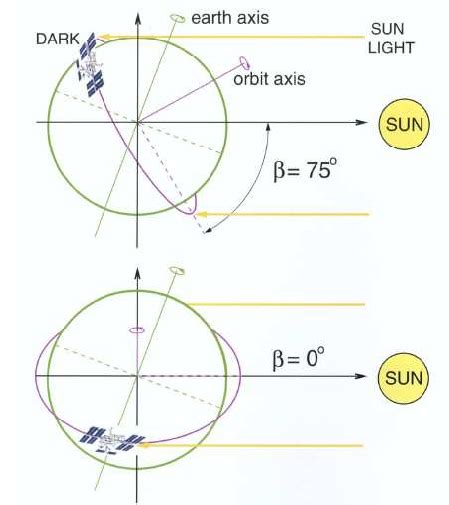

In the case of IonSat, the altitude and the beta angle will be changing depending on the initial deployment orbit.

Note that the initial deployment orbit is not fixed yet, because there is no confirmation on the launcher.

An example of an evolution of altitude and beta angle can be seen on the following images:

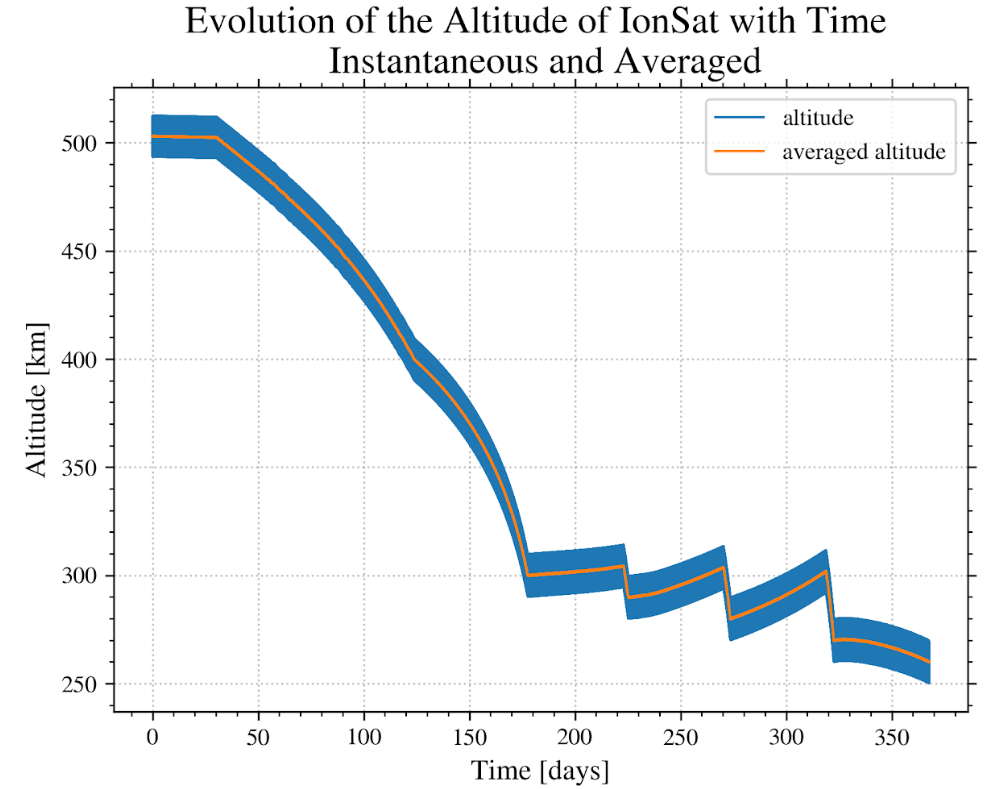

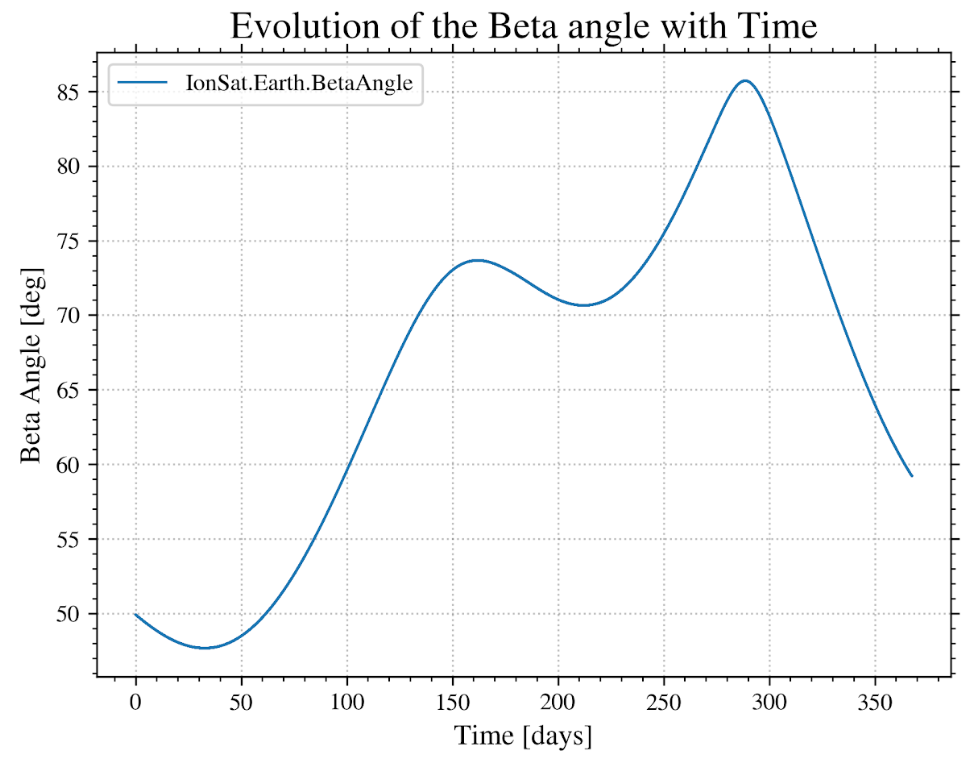

The beta angle is constantly changing, but the variation is very slow (only noticeable in days)

## 2. Creating the simulink

The simulink file created to generate the data is: ***CellSimulink.slx***

To run this file, the following Add-ons are required:

- Aerospace Blockset, 

- Aerospace Toolbox, 

- Ephemeris Data for Aerospace toolbox

Also, a user defined function called "eclipse_check.m" has to be on the Matlab path.

### Running the simulation

First, to initialize it, we need to configure some parameters:

clear all
close all

%Initialisation of date
date.year=2024;
date.month=9;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
orbit.R_earth=6378e3;
orbit.altitude=300e3;
orbit.a = 6678e3;       %semimajor axis [m]
orbit.e = 0.001;        %eccentricity
orbit.i = 98;           %inclination [degrees]
orbit.O = 50;            %Right ascension of the right ascending node [degrees] 
orbit.o = 0;            %Argument of the perigee [degrees]                      
orbit.nu = 0;           %True anomaly [degrees]
%In this case, RAAN=orbit.O is close to the Beta angle.

%time step  
TimeStep = 10;        %fixed-step size in solver, Default time step=0.25
Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
N_orbits = 2;           %number of orbits to be simulated
%Time spent performing the simulation in seconds (one orbit is ~5400 s):
t_sim = N_orbits*Torbit;

P_1cell=1.2; %Watt

MODE=4;         %"sun-aero" pointing mode
% 1: "orbital" Reference quaternion is aligned with ORF. 
% 2: "sun-aero" Reference quaternion is such that x is aligned with velocity 
%and z is aligned as best as possible with the sun direction to maximize the power generation 
% 3: "sun pointing" Reference quaternion is such that z is aligned with with 
%the sun direction to maximize the power generation and x is aligned as best 
%as possible with the velocity direction. 
% 4: "aero-drag" Reference quaternion is similar than in Case 1, but rotated 
%90° along the y axis, therefore, the reference quaternion is an attitude for 
%maximizing the drag surface. 
% 5: "retrogade firing" Reference quaternion is similar than in Case 1, but 
%rotated 180° along the z axis, therefore, the reference quaternion is an 
%attitude for retrograde propulsion. (??should be like case 2 but rotated?)
% 6: Reference quaternion is static [1 0 0 0], but this time is the only case 
%where the state of the B-dot is enabled (1). 
% 7: Reference quaternion is a custom quaternion that has to be defined by the 
%user as an input to the mission block. 


To run the simulation:

%% Simulation
CellSimulink              %MATLAB R2020b
data=sim('CellSimulink');

We can plot the results as:

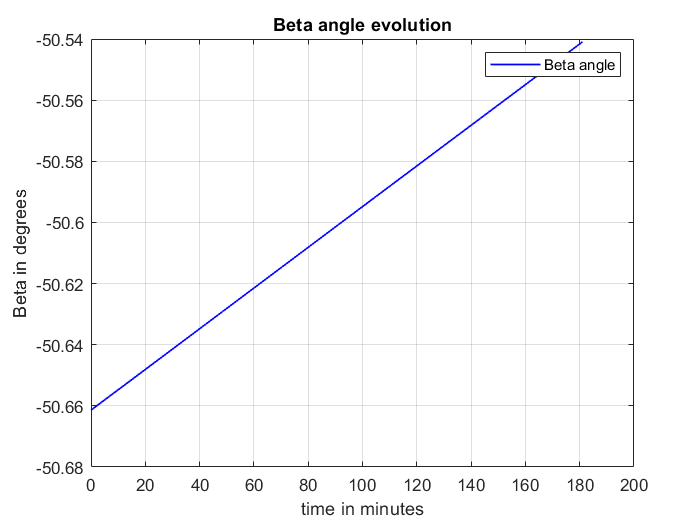

timesec = data.tout;
sat_beta = getdatasamples(data.beta,(1:length(timesec)));
PcellX1 = getdatasamples(data.PcellX1,(1:length(timesec)));
PcellX2 = getdatasamples(data.PcellX2,(1:length(timesec)));
eclipse = getdatasamples(data.eclipse,(1:length(timesec)));
angleX1 = getdatasamples(data.angle1,(1:length(timesec)));
angleX2 = getdatasamples(data.angle2,(1:length(timesec)));
%plot the beta angle
figure(1)
        set(gcf,'color','w');
        plot(timesec/60,sat_beta(:,1),'b','LineWidth',1)
        hold on;
        legend('Beta angle')
        title('Beta angle evolution')
        ylabel('Beta in degrees')
        xlabel('time in minutes')
        grid on

We can plot the angle to the normal of the surface:

Angle = 0 degrees -> maximum illumination

Angle = 90 degrees -> parallel to the surface, zero illumination

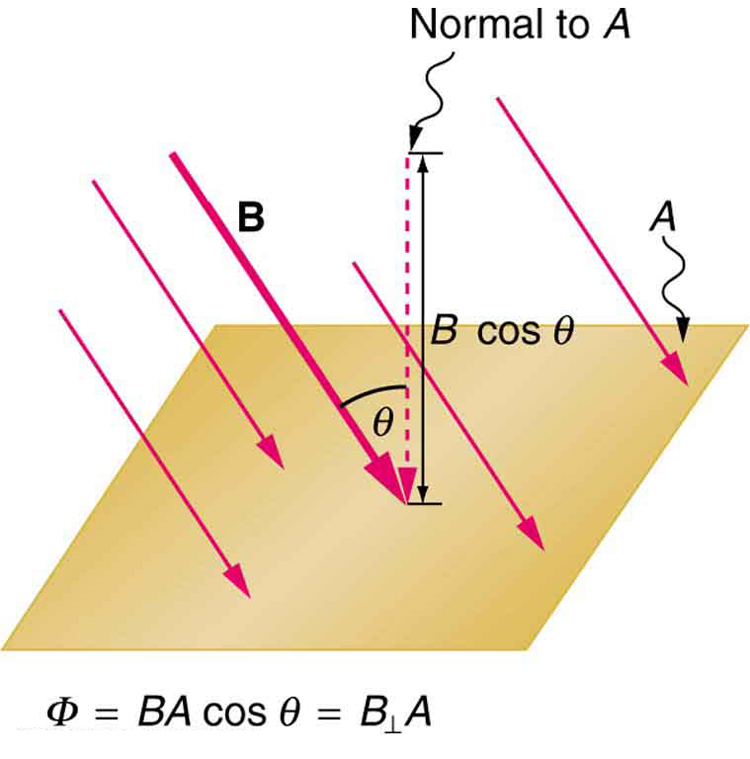

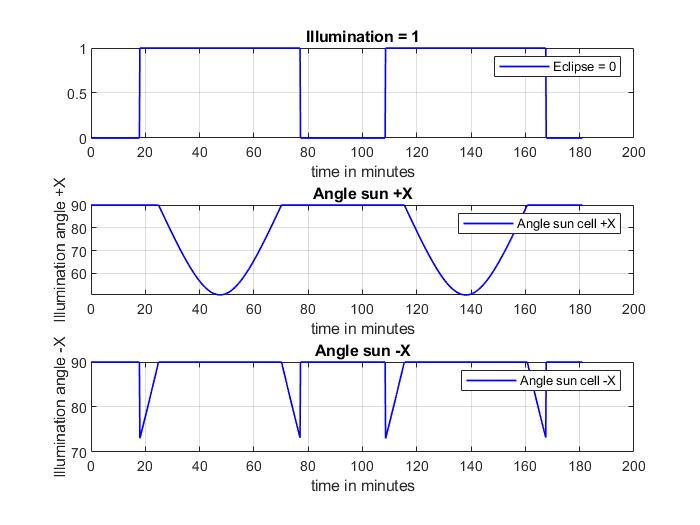

figure(2)
    subplot(3,1,1)
        set(gcf,'color','w');
        plot(timesec/60,eclipse(:,1),'b','LineWidth',1)
        hold on;
        legend('Eclipse = 0')
        title('Illumination = 1')
        %ylabel('Beta in degrees')
        xlabel('time in minutes')
        grid on
    subplot(3,1,2)
        set(gcf,'color','w');
        plot(timesec/60,angleX1(:,1),'b','LineWidth',1)
        hold on;
        legend('Angle sun cell +X')
        title('Angle sun +X')
        ylabel('Illumination angle +X')
        xlabel('time in minutes')
        grid on
    subplot(3,1,3)
        set(gcf,'color','w');
        plot(timesec/60,angleX2(:,1),'b','LineWidth',1)
        hold on;
        legend('Angle sun cell -X')
        title('Angle sun -X')
        ylabel('Illumination angle -X')
        xlabel('time in minutes')
        grid on

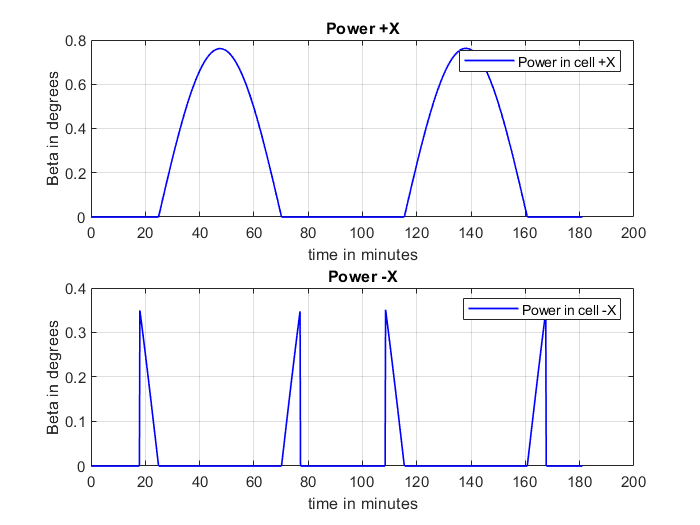

figure(3)
    subplot(2,1,1)
        set(gcf,'color','w');
        plot(timesec/60,PcellX1(:,1),'b','LineWidth',1)
        hold on;
        legend('Power in cell +X')
        title('Power +X')
        ylabel('Beta in degrees')
        xlabel('time in minutes')
        grid on
    subplot(2,1,2)
        set(gcf,'color','w');
        plot(timesec/60,PcellX2(:,1),'b','LineWidth',1)
        hold on;
        legend('Power in cell -X')
        title('Power -X')
        ylabel('Beta in degrees')
        xlabel('time in minutes')
        grid on